# **UWB Localization Using IEEE 802.15.4z**

% UWB Localization Using IEEE 802.15.4z with Channel Selection, 
% LOS/NLOS Conditions, and Enhanced CIR Visualization
% Author: 2024 Camille LANFREDI

### ** All the associated functions**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Localization 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% uwbChannel
% uwbChannelConfig
% helperShowLocations
% helperFindFirstHRPPreamble
% helperGetHyperbolicSurface
% helperFindHyperbolicIntersection
% displayBlink
% zoomInToEstimationArea

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Theoretical Channel Impulsive Response (MAC & Phy Layers)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% uwbChannel
% helperApplyChannel - GAINS & PHASES
% helperVisualizeChannelGains
% saveIntoCSVDataset

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Real Values from Measurements 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% readCIRValuesFromMeasurments
% displayCIRFromMeasurments
% displaySuperposeCIRFromMeasurments
% helperCalculateFirstPathAmplitudes
% helperCalculateSignalLevelDifference
% helperFindFirstPathLOS
% helperFindFirstPathNLOS
% helperSelectAndValidatePathGains

## *Setup*

Confirm installation of the Communications Toolbox™ Library for ZigBee® and UWB add-on.

% Confirm installation of the Communications Toolbox™ Library for 
% ZigBee® and UWB add-on.
% commSupportPackageCheck('ZIGBEE');

### Configure Network

Set up a network with 3 synchronized nodes and 1 device, in a 100x100 plane:

clear;
clc;

% % Set up a network with X synchronized nodes and Y device, in a 100x100 plane:

numDevices = 1;
numNodes = 3;

% Coordinates of each equipment
deviceLoc = [50 50];  % place device at the center
nodeLoc = [40 41; 
           62 83; 
           87 24];

% Initialize LOS/NLOS configuration
LOS = false(numDevices, numNodes);
for deviceIdx = 1:numDevices
    for node = 1:numNodes
        prompt = sprintf('Is the link between Device %d and Node %d LOS? (1 for YES, 0 for NO): ', deviceIdx, node);
        LOS(deviceIdx, node) = input(prompt);
    end
end

Calculate the actual distance and time of flight (TOF) between nodes and the device.

actualDistances = pdist2(nodeLoc, deviceLoc)

actualDistances =    13.4536
   35.1141
   45.2217


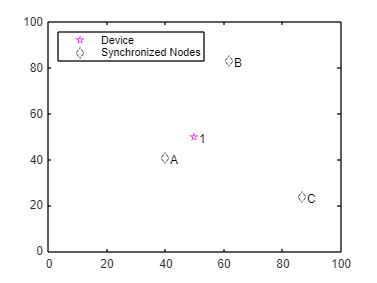

c = physconst('LightSpeed'); % speed of light (m/s)
actualTOF = actualDistances/c;
% Not sure
sampleRate = 1e9;
samplesToDelay = actualTOF * sampleRate;
TDOA = nan(numNodes, numDevices);
helperShowLocations(deviceLoc, nodeLoc);


% Change with your data
SNR = 30;  % in dB

#### Received Signals at each node with delays applied

% % Assuming a simple pulse signal
% txSignal = [1; zeros(999, 1)];  % Short pulse followed by zeros
% 
% % Apply calculated delays to the signal for each node
% for node = 1:numNodes
%     delay = round(samplesToDelay(node));  % Round to nearest sample
%     rxSignals(:, node) = [zeros(delay, 1); txSignal(1:end-delay)];  % Shift signal
% end
% % Plot to visualize
% figure;
% plot(rxSignals);
% legend('Node 1', 'Node 2', 'Node 3', 'Node 4', 'Node 5', 'Node 6');
% title('Received Signals at Each Node with Delays Applied');
% xlabel('Time (s)');
% ylabel('Signal Amplitude');

## *Channel Models*

### **Channel Parameterization**

The goal is to select the channel 9 or channel 5

Channel model based on IEEE : [https://www.ieee802.org/15/pub/04/15-04-0662-02-004a-channel-model-final-report-r1.pdf](https://www.ieee802.org/15/pub/04/15-04-0662-02-004a-channel-model-final-report-r1.pdf)

**Environment**

The IEEE 802.15.4a channel modeling subgroup recommends multiple UWB models for the 2 to 10 GHz range, which cover a wide range of environments:

- Industrial

- Indoor office

The subgroup recommends a LOS and a non-LOS model for each environment type, except for open outdoor, depending on the presence of a **line-of-sight (LOS)** component. Therefore, this example implements a total of nine combinations (type x LOS) for the 2 to 10 GHz range.

environmentType ="Industrial";

You can create custom environment scenarios by modifying the configuration presets above.

### **Frequency-Dependent Path Loss**

The environment and LOS configuration determine the frequency exponent `κ`. The channel specification in the IEEE 802.15.4a/z amendments determines the center frequency and channel bandwidth.

% Ensure channelSpec is defined correctly as a vector with three elements
% Channel 9 = 8Ghz | Channel 5 = 6.5 GHz
channelSpec = [5, 6489.6e6, 499.2e6]; 
channelNum = channelSpec(1);
Fc = channelSpec(2);
bw = channelSpec(3);
fprintf('Channel #%d: Center frequency = %.1f MHz, Bandwidth = %.1f MHz.\n', channelNum, Fc/1e6, bw/1e6);

Channel #5: Center frequency = 6489.6 MHz, Bandwidth = 499.2 MHz.


% Loop over each device-node pair to configure environment
env = cell(numDevices, numNodes);
for deviceIdx = 1:numDevices
    for node = 1:numNodes
        env{deviceIdx, node} = uwbChannelConfig(environmentType, LOS((deviceIdx-1)*numNodes + node));
    end
end

### Configure Blinks

Use a short (IEEE 802.15.4 MAC) data frame as a blink.

numBlinks = 1;

### MAC Layer : A AUTOMATISER

payload = '00'; % represents the data you send through the UWB channel.
cfg = lrwpan.MACFrameConfig( ...
        FrameType='Data', ...
        DestinationAddressing='Short address', ... %affects the size and structure of the frame : Short = 16 bits Long = 64 bits
        SourceAddressing='Short address', ...
        SourcePANIdentifier='AB12', ...
        SourceAddress='CD77')

cfg =   MACFrameConfig with properties:

                       FrameType: 'Data'

   General MAC properties:
                  SequenceNumber: 0
           AcknowledgmentRequest: 0
           DestinationAddressing: 'Short address'
        DestinationPANIdentifier: '0000'
              DestinationAddress: '0001'
                SourceAddressing: 'Short address'
             SourcePANIdentifier: 'AB12'
                   SourceAddress: 'CD77'
    PANIdentificationCompression: 0
                    FramePending: 0
                    FrameVersion: '2011'
                        Security: 0

   Security properties:
    No properties.

   Beacon properties:
    No properties.

   "MAC Command" properties:
    No properties.


% blinkMAC = lrwpan.MACFrameGenerator(cfg,payload);
blinkMAC = lrwpan.MACFrameGenerator(cfg,payload);

### PHY Layer :

% Also set the proper PSDU length.
blinkPHYConfig = lrwpanHRPConfig( ...
    Mode='HPRF', ...
    Channel=channelNum,...
    STSPacketConfiguration=1, ...
    STSSegmentLength=16,...
    PHRDataRate=6.81,...
    PSDULength=length(blinkMAC)/8, ...
    PreambleDuration="16",...
    Ranging=true);

### Standard Waveform :

blinkPHY = lrwpanWaveformGenerator(blinkMAC, blinkPHYConfig);

### Results :

Pour plus d'information : [***https://it.mathworks.com/help/comm/ug/hrp-uwb-ieee-802.15.4az-waveform-generation.html***](https://it.mathworks.com/help/comm/ug/hrp-uwb-ieee-802.15.4az-waveform-generation.html)

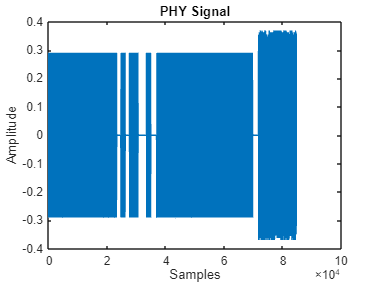

% disp('Sample Rate:');
% disp(blinkPHYConfig.SampleRate);

figure;
plot(blinkPHY);
title('PHY Signal');
xlabel('Samples');
ylabel('Amplitude');


% Cache preamble, to use in preamble detection. 
% Get the 1st instance out of the Nsync=PreambleDuration repetitions.
indices = lrwpanHRPFieldIndices(blinkPHYConfig); % length (start/end) of each field
blinkPreamble = blinkPHY( ...
    1:indices.SYNC(end)/blinkPHYConfig.PreambleDuration); % 1 of the Nsync repetitions

## *Theoretical Channel Impulsive Response *

Script :

% Initialise the output file
outputFileName = 'pathGains_all_devices_nodes_amplitude.csv';

% If the file exists, read its content
if isfile(outputFileName)
    existingData = readcell(outputFileName);
else
    existingData = {};
end

% Iterations is use to build your dataset base on your config (uwb channel +
% anchors and tags)
iterations = 1;

% Initialize the cell to store path gains
pathGainsCell = cell(numDevices, numNodes);


for iter = 1:iterations
    disp('=================================================================');
    fprintf('Iteration %d\n', iter);
    disp('=================================================================');

    for deviceIdx = 1:numDevices
        for node = 1:numNodes
            envConfig = uwbChannelConfig(environmentType, LOS(deviceIdx, node));

            % Configure the UWB channel
            UWBChannel = uwbChannel(environmentType, LOS(deviceIdx, node), ...
                'TransmitPower', 74.131e-9 * Fc, ...
                'Distance', actualDistances(node, deviceIdx), ...
                'ChannelNumber', channelNum, ...
                'LastPathThreshold', 0.05, ...
                'SampleRate', blinkPHYConfig.SampleRate, ...
                'SampleDensity', 1e5, ...
                'MaxDopplerShift', 5, ...
                'ChannelFiltering', false);

            % Obtain the channel realization (path gains)
            pathGains = UWBChannel();

            % Get the channel information
            s = info(UWBChannel);

            % Save CIR values into a struct
            CIR_values(deviceIdx, node).pathGains = pathGains;
            CIR_values(deviceIdx, node).info = s;

            % Store the path gains in the cell
            pathGainsCell{deviceIdx, node} = pathGains;

            % Visualize the channel gains
            helperVisualizeChannelGains(s.ClusterArrivalTimes, s.PathArrivalTimes, pathGains);

            % Initialize a variable to hold the combined path gains
            combinedPathGains = [];

            % Determine the maximum length of the path gains arrays
            maxLength = max(cellfun(@(x) length(x), pathGains(:)));

            % Iterate over each path gain component
            for i = 1:length(pathGains)
                pathGainComponent = pathGains{i}(:);
                paddedPathGainComponent = [pathGainComponent; zeros(maxLength - length(pathGainComponent), 1)];
                combinedPathGains = [combinedPathGains, paddedPathGainComponent];
            end

            summedPathGains{deviceIdx, node} = sum(abs(combinedPathGains), 2);

            % Call the display function
            displayCIRFromTheoreticalModel(pathGains, s.ClusterArrivalTimes, s.PathArrivalTimes);

            % Store path gains for superposition if it's the first two devices and nodes
            if deviceIdx <= 2 && node == 1
                superposePathGains{deviceIdx} = pathGains;
            end

            % Debugging: Display information about stored path gains
            if deviceIdx <= 2 && node == 1
                disp(['Device ', num2str(deviceIdx), ' Node ', num2str(node)]);
                disp(superposePathGains{deviceIdx});
            end
        end
    end

### The reference path loss PL0 and path loss PLd

You can add the deviation of shadowing (S) based on the propagation model :

####  

Iteration 1


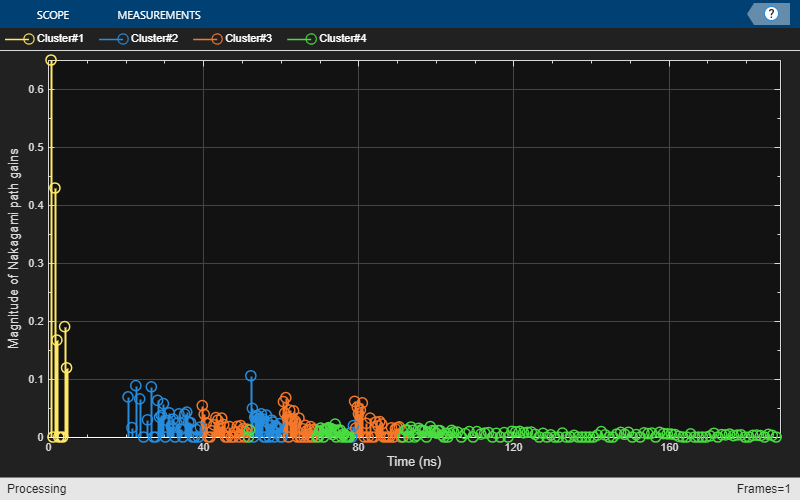

Total samples in helperVisualizeChannelGains: 562


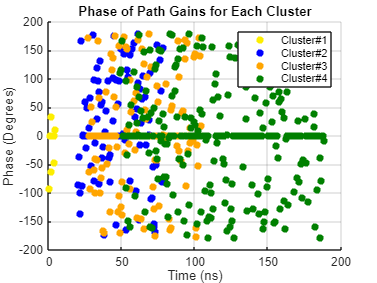

Total samples in displayCIRFromTheoreticalModel: 562


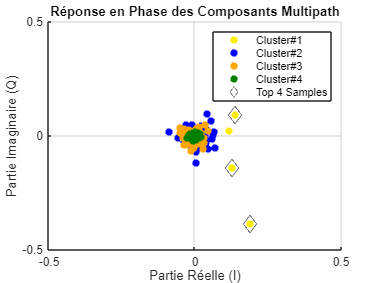

Device 1 Node 1


    {[-0.0269 - 0.6491i 0.0000 + 0.0000i 0.1904 - 0.3845i 0.1386 + 0.0929i 0.0000 + 0.0000i 0.0000 + 0.0000i 0.0000 + 0.0000i 0.1277 - 0.1409i 0.1172 + 0.0225i]}    {[0.0047 - 0.0688i 0.0709 - 0.0541i -0.0118 - 0.0109i -0.0086 - 0.0465i -0.0862 + 0.0199i 0.0066 - 0.1189i 0.0655 + 0.0029i 0.0000 + 0.0000i 0.0000 + 0.0000i 0.0245 + 0.0432i 0.0277 - 0.0105i 0.0000 + 0.0000i 0.0563 + 0.0657i 0.0000 + 0.0000i 0.0672 + 0.0166i 0.0000 + 0.0000i 0.0421 + 0.0968i 0.0000 + 0.0000i 0.0455 - 0.0575i 0.0000 + 0.0000i -0.0493 + 0.0018i 0.0108 - 0.0550i -0.0076 + 0.0489i 0.0618 - 0.0128i 0.0000 + 0.0000i 0.0434 + 0.0255i -0.0268 + 0.0489i -0.0039 + 0.0339i 0.0072 + 0.0333i 0.0037 - 0.0349i -0.0326 + 0.0369i 0.0211 + 0.0306i 0.0187 + 0.0316i 0.0258 - 0.0205i 0.0307 - 0.0109i -0.0572 - 0.0063i 0.0364 + 0.0042i 0.0000 + 0.0000i 0.0252 + 0.0243i 0.0000 + 0.0000i -0.0040 + 0.0313i 0.0000 + 0.0000i 0.0413 - 0.0319i 0.0045 - 0.0278i 0.0258 - 0.0166i 0.0000 + 0.0000i 0.0000 + 0.0000i 0.0371 + 0.0190i -0.0087

Number of clusters = 4


Incorrect number or types of inputs or outputs for function real.

Error in scatterplot (line 80)
    x = [real(x), imag(x)];

    %             % Calcul de la perte de chemin de référence en dB
    %              PL0 = 20 * log10((4 * pi * actualDistances(node, deviceIdx) * Fc) / c);
    %
    %             % Afficher la perte de chemin de référence
    %             fprintf('La perte de chemin de référence (PL0) à %.2f m et %.2f GHz est de %.2f dB.\n', actualDistances(node, deviceIdx), Fc/1e9, PL0);
    %
    %             % Modélisation du chemin et simulation du canal
    %             d = 10; % Distance entre l'émetteur et le récepteur, en mètres
    %             n = 3; % Exposant de la perte de chemin
    %             sigma = 2; % Déviation standard de l'ombrage
    %
    %             % Assurez-vous que 'env' est bien une structure
    %             env = struct();
    %             env.ReferencePathLoss = PL0; % Perte de chemin de référence pour l'environnement
    %             env.PathLossExponent = n; % Exposant de la perte de chemin pour l'environnement
    %             env.ShadowingDeviation = sigma; % Déviation standard de l'ombrage pour l'environnement
    %             % Définition de waveBPRF
    %
    %             waveBPRF = randn(1000, 1); % Exemple de signal aléatoire
    %
    %
    % % Calcul du signal reçu avec la perte de chemin
    % [rxSignal, PLd] = helperDistancePathLoss(waveBPRF, env.ReferencePathLoss, d, env.PathLossExponent, env.ShadowingDeviation);

    % Visualize received signal
    % figure;
    % plot(rxSignal);
    % title('received signal with path loss ');
    % xlabel('Samples');
    % ylabel('Amplitude');

### ***Dataset Creation***

*Description** :*

- Number of device and node

- Los/NLos

- CIR values

Then stock in the : ***pathGains_all_devices_nodes_amplitude.csv*** file.

*Script :*

    % Save the new data into the CSV file
    saveIntoCSVDataset(summedPathGains, numDevices, numNodes, LOS, outputFileName, existingData);

    % Update existingData with the new data for the next iteration
    existingData = readcell(outputFileName);
end
% Call the function to select and validate devices and nodes for superposition
% superposePathGains = helperSelectAndValidatePathGains(pathGainsCell, numDevices, numNodes);
% 
% % Call the superposition function
% displaySuperposeCIRFromTheoreticalModel(superposePathGains{1}, superposePathGains{2});

## *Real Channel Impulsive Responses (Measurements)*

`Script:` `Version 5 Implemented (processingCirDataMeasurmentV5)`

% file_paths = {'L1_R1_CIRs_Ch_9.txt', 'L1_R2_CIRs_Ch_9.txt', 'L1_R3_CIRs_Ch_9.txt'};
% displayCIRFromMeasurments(file_paths, LOS);

To compare CIRs in a complex plan. 

% filepaths = {'L1_R1_CIRs_Ch_9.txt', 'L1_R2_CIRs_Ch_9.txt'};
% displaySuperposeCIRFromMeasurments(filepaths);

## *TDoA : Lacolization based on coordinates*

### Run Simulation

In the **simulation loop**, a blink propagates to each node with a propagation delay that is determined by their distinct distance. Next, each pair of nodes calculates the difference of their blink arrival times. As a result, the position of the device is estimated within a hyperbolic surface for each pair of nodes. The intersection of all surfaces gives the position estimate for the device. Here, a plot of 2D curves shows the intersection point to indicate the position estimate for the device.

% Simulation loop
vfd = dsp.VariableFractionalDelay('InterpolationMethod', 'FIR', 'FilterHalfLength', 4, 'InterpolationPointsPerSample', 10);
plotStr = {'r--', 'b--', 'g--', 'm--', 'c--', 'k--'};

nodePairs = [1, 2; 1, 3; 2, 3];  % Use predefined pairs
numPairs = size(nodePairs, 1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Loop for each device
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for deviceIdx = 1:numDevices
    arrivalTime = zeros(1, numNodes); % Reset arrival times for each device

    xO = []; % Initialize xO and yO variables for each device
    yO = [];

    for idx = 1:numBlinks
        % First view of hyperbolic intersections 
        % New figure for each blink
        figure;
        hold on;
        % Plot nodes and devices
        plot(nodeLoc(:, 1), nodeLoc(:, 2), 'kd');
        for i = 1:size(nodeLoc, 1)
            text(nodeLoc(i, 1) + 1.5, nodeLoc(i, 2) - 1, char(64+i)); % Labels like A, B, C...
        end
        plot(deviceLoc(:, 1), deviceLoc(:, 2), 'mp');
        for j = 1:size(deviceLoc, 1)
            text(deviceLoc(j, 1) + 1.5, deviceLoc(j, 2) - 1, num2str(j)); % Labels like 1, 2, ...
        end

        for node = 1:numNodes
            tof = actualTOF(node, deviceIdx);
            samplesToDelay = round(tof * blinkPHYConfig.SampleRate); % ensure samplesToDelay is an integer

            reset(vfd);
            release(vfd);
            vfd.MaximumDelay = ceil(1.1 * max(samplesToDelay)); % Ensure this is set correctly
            delayedBlink = vfd([blinkPHY; zeros(ceil(samplesToDelay), 1)], samplesToDelay);

            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % LOS or NLOS CASES (you can change the constants)
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            if LOS(deviceIdx, node)
                receivedBlink = delayedBlink; % LOS condition
            else
                multipathDelay = round(0.3 * samplesToDelay);
                multipathSignal = 0.5 * vfd([blinkPHY; zeros(ceil(multipathDelay), 1)], multipathDelay);
                combinedSignal = [delayedBlink; zeros(length(multipathSignal) - length(delayedBlink), 1)];
                combinedSignal(1:length(multipathSignal)) = combinedSignal(1:length(multipathSignal)) + multipathSignal;
                receivedBlink = awgn(combinedSignal, SNR); % NLOS condition
            end
           
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % Filter the noise by thresholding
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % This part filters out low amplitude signals,
            % helping to highlight the significant peaks in the CIR.
            threshold = 3.98;       % Facteur pour détecter l'augmentation significative de la variance
                                                    % Indiqué dans le code
                                                    % Segger > dw3000_statistics.c > L188 
                                                    % Use in displayCIRFromMeasurments > L160
            filteredBlink = receivedBlink;
            filteredBlink(abs(receivedBlink) < threshold) = 0;

            % Identify the region of interest (around the impulse)
            regionStart = max(1, floor(samplesToDelay) - 50);
            regionEnd = min(length(filteredBlink), ceil(samplesToDelay) + 50);
            
            % Store the CIR data for plotting later
            CIRdata{node} = struct('delayedBlink', delayedBlink, 'filteredBlink', filteredBlink, ...
                                   'regionStart', regionStart, 'regionEnd', regionEnd);
                  
            preamPos = helperFindFirstHRPPreamble(receivedBlink, blinkPreamble, blinkPHYConfig);
            arrivalTime(node) = (preamPos - indices.SYNC(end) / blinkPHYConfig.PreambleDuration) / blinkPHYConfig.SampleRate;
        end

        % Plot hyperbolic surfaces and intersections
        xCell = cell(1, numPairs);
        yCell = cell(1, numPairs);
        for pairCnt = 1:numPairs
            node1 = nodePairs(pairCnt, 1);
            node2 = nodePairs(pairCnt, 2);
            TDOA = arrivalTime(node1) - arrivalTime(node2);
            [xCell{pairCnt}, yCell{pairCnt}] = helperGetHyperbolicSurface(nodeLoc(node1, :), nodeLoc(node2, :), TDOA);
            plot(xCell{pairCnt}, yCell{pairCnt}, plotStr{pairCnt}); % You can change colors and styles for better distinction
        end
        
        % Find intersections
        [xC, yC] = helperFindHyperbolicIntersection(xCell, yCell);

        % Estimate position
        xO = [xO; mean(xC)]; % Add new position estimates
        yO = [yO; mean(yC)];

        plot(xO, yO, 'ro');
        plot(xC', yC', 'rx');

        fprintf('Estimated coordinates: (%.3f, %.3f)\n', xO, yO);

        estimatedLoc = [xO(end), yO(end)];

        if size(estimatedLoc, 1) > 1
            estimatedLoc = estimatedLoc';
        end

        if size(estimatedLoc, 2) ~= size(nodeLoc, 2)
            error('The estimated location must have the same number of columns as the node locations.');
        end

        distancesToNodes = sqrt(sum((nodeLoc - estimatedLoc).^2, 2));

        disp('Distances to Nodes:');
        disp(distancesToNodes);
        differences = abs(distancesToNodes - actualDistances(:, deviceIdx));
        for node = 1:numNodes
            fprintf('Difference for Node %d: %.3f meters\n', node, differences(node));
        end
    end

    leg = legend( ...
        'Device', ...
        'Synchronized nodes', ...
        'A-B', ...
        'A-C', ...
        'B-C', ...
        'Estimation', ...
        'Intersections', ...
        'location', 'northwest');
        axis([0 100 0 100]);  % Fixer les limites des axes entre 0 et 100
        grid on;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Zoom view
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    figure;
    hold on;
    plot(nodeLoc(:, 1), nodeLoc(:, 2), 'kd');
    plot(deviceLoc(:, 1), deviceLoc(:, 2), 'mp');
    for pairIdx = 1:numPairs
        plot(xCell{pairIdx}, yCell{pairIdx}, plotStr{pairIdx});
    end
    plot(xO, yO, 'ro');
    plot(xC', yC', 'rx');

    zoomInToEstimationArea(deviceLoc(deviceIdx, :), xC, yC, xO, yO, leg);
    xlabel('X Coordinate (m)');
    ylabel('Y Coordinate (m)');
    hold off;

The IEEE 802.15.4z localization algorithm allows for multiple intersection points between 2 hyperbolic surfaces, thus either one or two possible localization answers exist. Calculate the localization error for each answer:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculer l'erreur de localisation pour chaque dispositif
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fprintf('Localization error for device %d:\n', deviceIdx);
    for idx = 1:numel(xO)
        locError = sqrt(sum(([xC(idx) yC(idx)] - deviceLoc(deviceIdx, :)).^2));
        fprintf('Localization error #%d = %0.3f m.\n', idx, locError);
    end
end

For localization methods that rely on estimating the time of arrival, errors in the distance estimate are primarily caused when the arrival time is not an integer multiple of the sample time. The largest distance error for such localization methods occurs when the arrival time lasts half a sample time more than an integer multiple of sample time. The smallest distance error occurs when the arrival time is an integer multiple of sample time. For the higher pulse repetition frequency (HRPF) mode of the high rate pulse repetition frequency (HRP) PHY used in this example, the symbol rate is 499.2 MHz and the number of samples per symbol is 10. The maximum distance estimation error is $0\ldotp 5\times c/\left(499\ldotp 2\times 10\right)$, which is approximately 3 cm.

In general, the larger channel bandwidth in UWB corresponds to shorter symbol duration and smaller ranging error as compared to narrowband communication. For the narrowband communication as specified in IEEE 802.11az, the channel bandwidth ranges from 20 MHz to 160 MHz. Considering the maximum distance error for narrowband communication, estimates for the localization error lie between 0 and 10 cm for 160 MHz and between 0 and 75 cm for 20 MHz. For more information regarding positioning with IEEE 802.11az, see the [802.11az Positioning Using Super-Resolution Time of Arrival Estimation](docid:wlan_ug#example-HERangingPositioningExample) example.

## Selected Bibliography

1 - "IEEE Standard for Low-Rate Wireless Networks," in IEEE Std 802.15.4-2020 (Revision of IEEE Std 802.15.4-2015), pp.1-800, 23 July 2020, doi: 10.1109/IEEESTD.2020.9144691.

2 - "IEEE Standard for Low-Rate Wireless Networks – Amendment 1: Enhanced Ultra Wideband (UWB) Physical Layers (PHYs) and Associated Ranging Techniques," in IEEE Std 802.15.4z-2020 (Amendment to IEEE Std 802.15.4-2020), pp.1-174, 25 Aug. 2020, doi: 10.1109/IEEESTD.2020.9179124.

3 - Wong, S.; Zargani, R. Jassemi; Brookes, D. & Kim, B. "Passive target localization using a geometric approach to the time-difference-of-arrival method", Defence Research and Development Canada Scientific Report, DRDC-RDDC-2017-R079, June 2017, pp. 1-77.

*Copyright 2021 The MathWorks, Inc.*

*Copyright 2024 Camille Lanfredi*

[*https://it.mathworks.com/help/wlan/ug/three-dimensional-indoor-positioning-with-802-11az-fingerprinting-and-deep-learning.html*](https://it.mathworks.com/help/wlan/ug/three-dimensional-indoor-positioning-with-802-11az-fingerprinting-and-deep-learning.html)